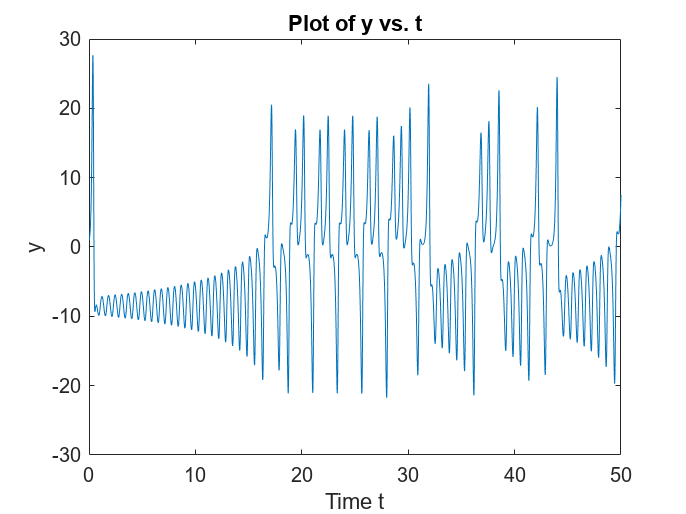

%1
sig = 10;
b = 8/3;
r = 28;
lorenz = @(t, X) [sig * (X(2) - X(1)); 
                  r * X(1) - X(2) - X(1) * X(3); 
                  X(1) * X(2) - b * X(3)];

X0 = [0; 1; 0];
tspan = [0 50];
[t, X] = ode45(lorenz, tspan, X0);

%a
figure;
plot(t, X(:,2));
title('Plot of y vs. t');
xlabel('Time t');
ylabel('y');

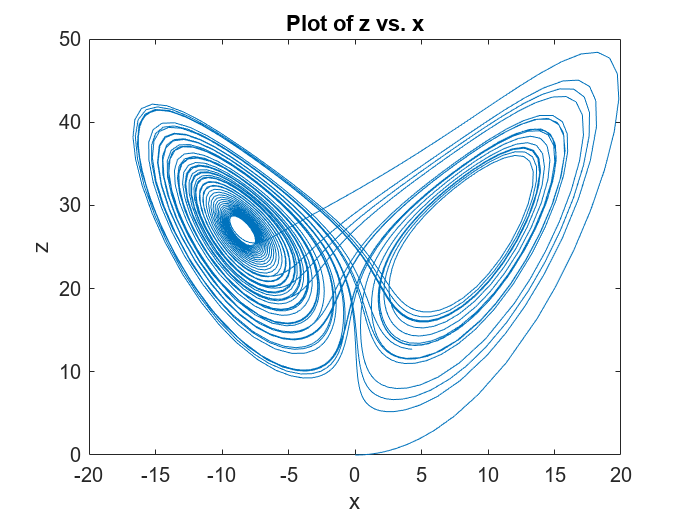


%b
figure;
plot(X(:,1), X(:,3));
title('Plot of z vs. x');
xlabel('x');
ylabel('z');

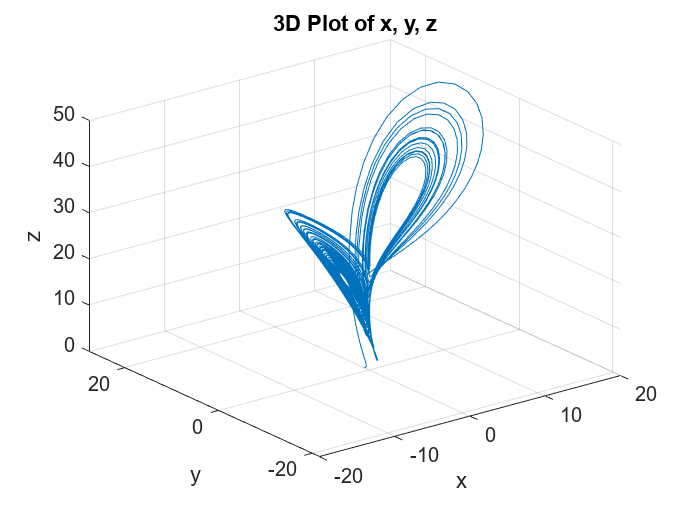


%c
figure;
plot3(X(:,1), X(:,2), X(:,3));
title('3D Plot of x, y, z');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

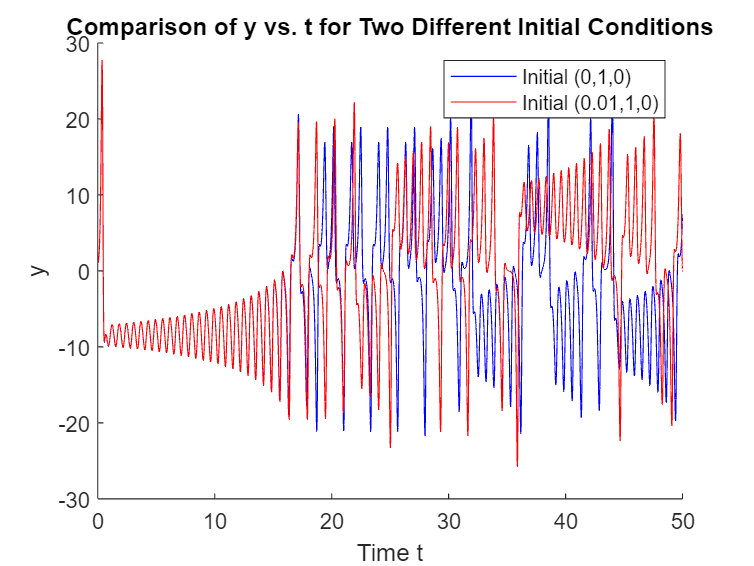


%2
X0_new = [0.01; 1; 0];
[t_new1, X_new1] = ode45(lorenz, tspan, X0_new);

figure;
hold on;
plot(t, X(:,2), 'b');
plot(t_new1, X_new1(:,2), 'r');
title('Comparison of y vs. t for Two Different Initial Conditions');
xlabel('Time t');
ylabel('y');
legend('Initial (0,1,0)', 'Initial (0.01,1,0)');

Question 3

x=y,z=xy/b�,0=rx−y−x^2*y/b�

0=rx−x−x^3/b

x=sqrt(r−1)/b,y=x,z=x^2/b�

(x,y,z)=(±sqrt(b(r−1))�,±sqrt(b(r−1))�,(r−1)�)�

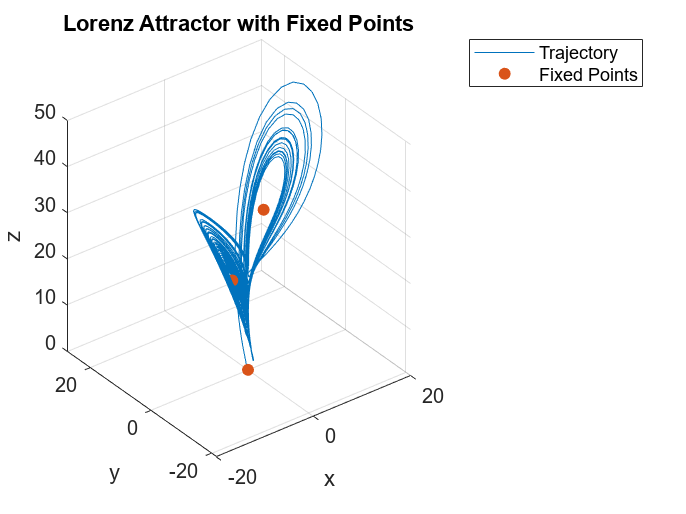

%3
fixed_points = [0 0 0; sqrt(b*(r-1)) sqrt(b*(r-1)) r-1; -sqrt(b*(r-1)) -sqrt(b*(r-1)) r-1];
figure;
plot3(X(:,1), X(:,2), X(:,3));
hold on;
scatter3(fixed_points(:,1), fixed_points(:,2), fixed_points(:,3), 'filled');
title('Lorenz Attractor with Fixed Points');
xlabel('x');
ylabel('y');
zlabel('z');
legend('Trajectory', 'Fixed Points');
grid on;


%4
syms x y z
J_sym = [-sig, sig, 0; 
         r-z, -1, -x; 
         y, x, -b];
J_fixed = subs(J_sym, [x, y, z], [sqrt(beta*(r-1)), sqrt(beta*(r-1)), (beta*(r-1))/beta]);

syms lambda
char_eqn = det(J_fixed - lambda * eye(3));

char_eqn_simplified = simplify(char_eqn);
disp('Characteristic Equation:')

Characteristic Equation:


disp(char_eqn_simplified)

$$-\lambda^{3}-\frac{41\,\lambda^{2}}{3}-\frac{304\,\lambda }{3}-1440$$


eigenvalues = solve(char_eqn_simplified == 0, lambda);

disp('Eigenvalues:')

Eigenvalues:


disp(eigenvalues)

$$\left(\begin{array}{c} \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,1\right)\\ \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,2\right)\\ \mathrm{root}\left(z^{3}+\frac{41\,z^{2}}{3}+\frac{304\,z}{3}+1440,z,3\right) \end{array}\right)$$


%5
r_H = sig * (sig + b + 3) / (sig - b - 1);
disp('r_H:')

r_H:


disp(r_H)

   24.7368



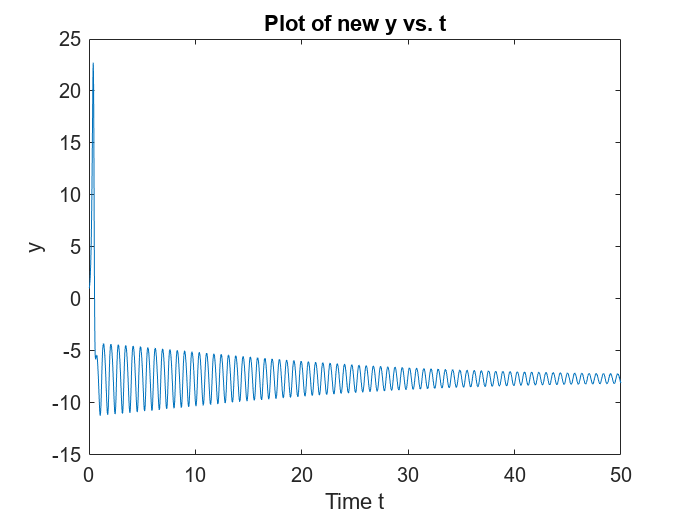


% Choice of new r < r_H
r_new = 23;

lorenz_new = @(t, X) [sig * (X(2) - X(1)); 
                      r_new * X(1) - X(2) - X(1) * X(3); 
                      X(1) * X(2) - b * X(3)];

[t_new2, X_new2] = ode45(lorenz_new, tspan, X0);

%5-1a
figure;
plot(t_new2, X_new2(:,2));
title('Plot of new y vs. t');
xlabel('Time t');
ylabel('y');

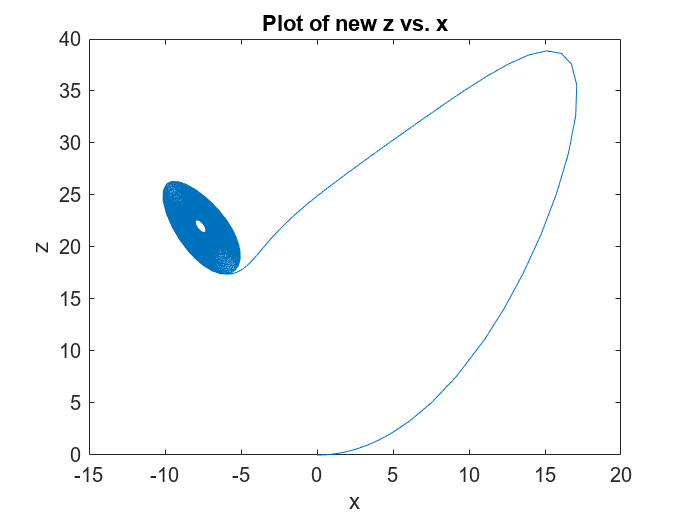


%5-1b
figure;
plot(X_new2(:,1), X_new2(:,3));
title('Plot of new z vs. x');
xlabel('x');
ylabel('z');

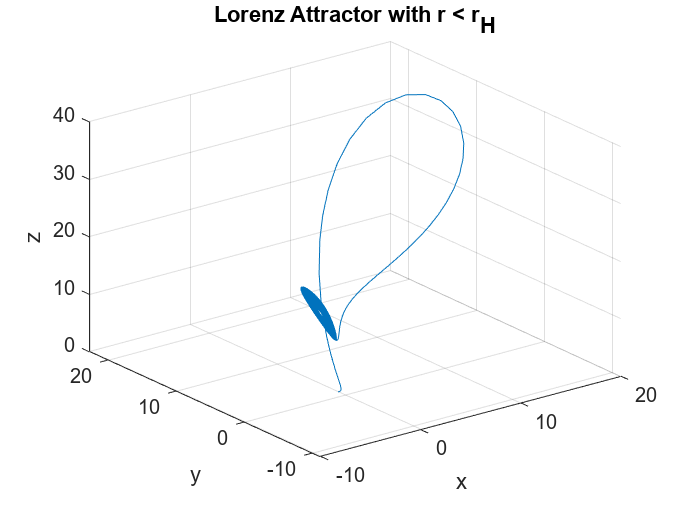


%5-1c
figure;
plot3(X_new2(:,1), X_new2(:,2), X_new2(:,3));
title('Lorenz Attractor with r < r_H');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

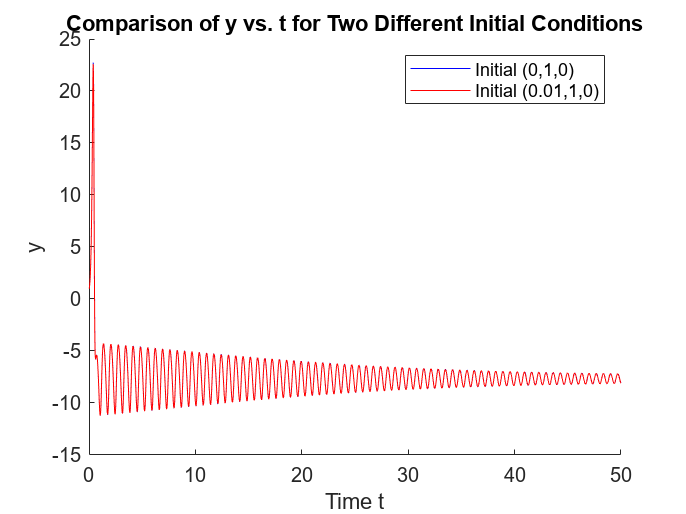


%5-2
X0_new = [0.01; 1; 0];
[t_new3, X_new3] = ode45(lorenz_new, tspan, X0_new);

figure;
hold on;
plot(t_new2, X_new2(:,2), 'b');
plot(t_new3, X_new3(:,2), 'r');
title('Comparison of y vs. t for Two Different Initial Conditions');
xlabel('Time t');
ylabel('y');
legend('Initial (0,1,0)', 'Initial (0.01,1,0)');

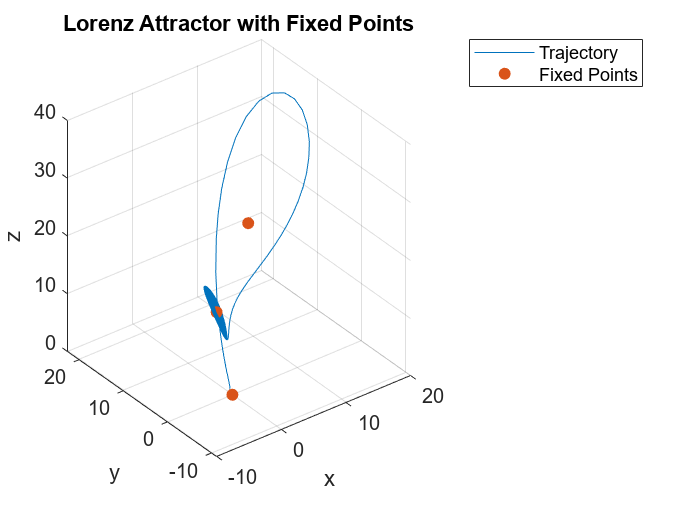


%5-3
fixed_points = [0 0 0; sqrt(b*(r_new-1)) sqrt(b*(r_new-1)) r_new-1; -sqrt(b*(r_new-1)) -sqrt(b*(r_new-1)) r_new-1];
figure;
plot3(X_new2(:,1), X_new2(:,2), X_new2(:,3));
hold on;
scatter3(fixed_points(:,1), fixed_points(:,2), fixed_points(:,3), 'filled');
title('Lorenz Attractor with Fixed Points');
xlabel('x');
ylabel('y');
zlabel('z');
legend('Trajectory', 'Fixed Points');
grid on;